l_1=0.333;
l_2=0.316;
l_3=0.0825;
l_4=0.384;
l_5=0.088;

radian1=pi/180;

lim1_min = -2.393 ; lim1_max = 2.3093; 
lim2_min = -1.5133 ; lim2_max = 1.5133; 
lim3_min = -2.4937 ; lim3_max = 2.4937; 
lim4_min = -2.7478 ; lim4_max = -0.4461; 
lim5_min = -2.480 ; lim5_max = 2.480; 
lim6_min = 0.8521 ; lim6_max = 4.2094; 
lim7_min = -2.6895 ; lim7_max = 2.695;

%            theta;    d;    a;     alpha
L(1) = Link([0,     l_1,    0,      0],'modified');
L(1).qlim=[lim1_min,lim1_max];

L(2) = Link([0,     0,      0,      -pi/2],'modified');
L(2).qlim=[lim2_min,lim2_max];

L(3) = Link([0,     l_2,    0,      pi/2],'modified');
L(3).qlim=[lim3_min,lim3_max];

L(4) = Link([0,     0,      l_3,    pi/2],'modified');
L(4).qlim=[lim4_min,lim4_max];

L(5) = Link([0,     l_4,    -l_3,   -pi/2],'modified');
L(5).qlim=[lim5_min,lim5_max];

L(6) = Link([0,     0,      0,      pi/2],'modified');
L(6).qlim=[lim6_min,lim6_max];

L(7) = Link([0,     0,      l_5,      pi/2],'modified');
L(7).qlim=[lim7_min,lim7_max];

Franka=SerialLink(L,'name','Franka');

Franka.tool = transl(0 ,0 ,0.107);

% joint_start = [-0.062298  1.163759 -1.131272  0.839999 -0.55264   0.873418 -0.810038];
joint_start = [0 0 0 0 0 0 0];


T=Franka.fkine(joint_start)

 

T = 
    1.0000    0.0000    0.0000       0.5
    0.0000   -0.0000   -1.0000   0.09999
   -0.0000    1.0000   -0.0000       0.7
         0         0         0         1



figure
Franka.plot(joint_start);

% figure
% % plot([0.])
% Franka.teach()

Inverse Kinematic

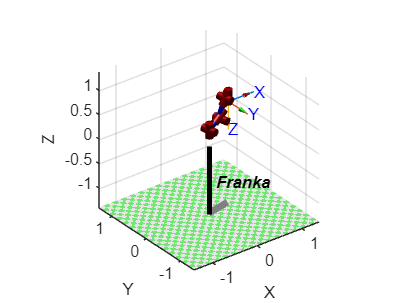

T= transl(0.5, 0.1, 0.7) * rpy2tr(pi, 0, 0);

qi = Franka.ikine(T);

figure
Franka.plot(qi);

Jocobian Matrix

% J = Franka.jacob0([joint_start])

Workspace-Monte Carlo method

% N=2000;   %random number
% theta1=lim1_min + (lim1_max-lim1_min)*rand(N,1); 
% theta2=lim2_min + (lim2_max-lim2_min)*rand(N,1);
% theta3=lim3_min + (lim3_max-lim3_min)*rand(N,1);
% theta4=lim4_min + (lim4_max-lim4_min)*rand(N,1);
% theta5=lim5_min + (lim5_max-lim5_min)*rand(N,1);
% theta6=lim6_min + (lim6_max-lim6_min)*rand(N,1);
% theta7=lim7_min + (lim7_max-lim7_min)*rand(N,1);
% pos = {1,N};
% 
% for i=1:N
%     pos{i}=Franka.fkine([theta1(i) theta2(i) theta3(i) theta4(i) ...
%         theta5(i) theta6(i) theta7(i)]);
% end
% 
% figure
% Franka.plot(joint_start,'jointdiam',1)
% axis equal;
% hold on;
% 
% 
% for i=1:N
%     plot3(pos{i}.t(1),pos{i}.t(2),pos{i}.t(3),'r.');
%     hold on;
% end
% grid off